# Third part - finger input

close all; clear all; clc;

## FINGER ONLY CART

As first passage we extract the data:

data = load('finger_only_cart.txt');
time = data(:, 1);      % time values
acc = data(:, 3);       % accelerations values

## 3.1 Sampling Frequency and meaningful time window

Compute sampling frequency:

number_of_samples = size(acc,1);
total_time = max(time);
fs = number_of_samples/total_time;

Take a look to the original signal:

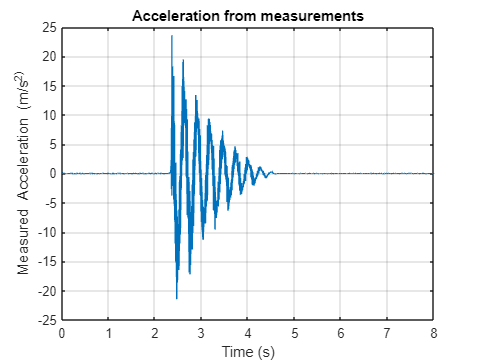

figure(1), clf
plot(time, acc);
xlabel('Time (s)');
ylabel('Measured Acceleration (m/s^2)');
title('Acceleration from measurements');
grid on

Let's find the indexes corresponding to the meaningful time window:

start_time = 2.29;
end_time = 4.65;
start_index = find(time >= start_time, 1);
end_index = find(time >= end_time, 1);

Now we are able to extract the meaningful time window:

time_window = time(start_index:end_index);
acc_window = acc(start_index:end_index);

Let's observe the plot:

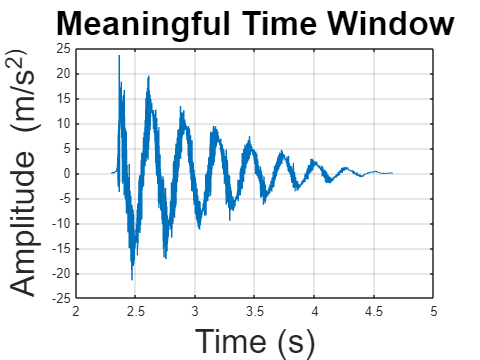

figure(2), clf
plot(time_window, acc_window);
xlabel('Time (s)','FontSize',15);
ylabel('Amplitude (m/s^2)','FontSize',15);
title('Meaningful Time Window','FontSize',15);
grid on

It is clear we have a non neglicible component of noise.

## 3.2 Filtering the noise, find peaks position and the magnitude

In order to have a smooth sinal we can perform a filtering, by computing the moving average on, for example, 1000 samples. We perform the smoothing twice.

We perform the same passages as for the last request.

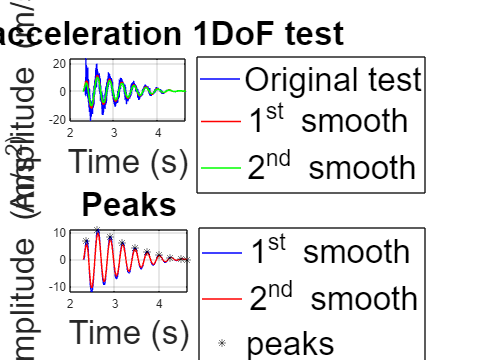

n1 = 1000;
s_smooth_cart = smooth(acc_window,n1);
n2 = 1000;
s_smooth2_cart = smooth(s_smooth_cart,n2);

[peak_val, peak_loc] = findpeaks(s_smooth2_cart);
peaks = s_smooth_cart(peak_loc);
peak_time = time_window(peak_loc);

figure(3)
subplot(2,1,1)
plot(time_window, acc_window,'b')
hold on
plot(time_window, s_smooth_cart, 'r','LineWidth', 1.3)
plot(time_window, s_smooth2_cart, 'g','LineWidth', 1.3)
xlabel('Time (s)','FontSize',15);
ylabel('Amplitude (m/s^2)','FontSize',15);
title('Cart acceleration 1DoF test','FontSize',15);
legend('Original test', '1^{st} smooth', '2^{nd} smooth','FontSize',25);
legend('Location','eastoutside');
grid on

subplot(2,1,2)
plot(time_window, s_smooth_cart,'b')
hold on
plot(time_window, s_smooth2_cart,'r')
plot(peak_time, peaks, 'k*')
xlabel('Time (s)','FontSize',15);
ylabel('Amplitude (m/s^2)','FontSize',15);
title('Peaks','FontSize',15);
legend('1^{st} smooth', '2^{nd} smooth', 'peaks', 'FontSize',15');
legend('Location','eastoutside');
grid on

## 3.3 Logarithmic Decrement Technique

We perform the logarithmic decrement method as we did before.

delta = log(peaks(2:8)./peaks(3:9));            % logarithmic decrements
mean_delta = mean(delta);                       % average of delta; 6 df
std_delta = std(delta);
T_d = diff(peak_time(2:9));                     % vector of periods of oscillation

Now we can compute the asked quantities with the relative standard deviations:

In some cases we have to use the propagation of error formula:

mean_period = mean(T_d);    % 6 df
std_period = std(T_d);

xi = mean_delta / sqrt(4*pi^2 + mean_delta^2);   % mean damping ratio
std_xi = sqrt(((1/(sqrt(4*pi^2 + mean_delta^2)))-((mean_delta^2/((4*pi^2 + mean_delta^2)^(3/2)))))^2 * std_delta^2);

omega_d = 2*pi / mean_period;                       % natural frequency
std_omega_d = sqrt((-(2*pi)/((mean_period)^2))^2 * std_period^2);

omega_n = omega_d / sqrt(1 - xi^2); % damped natural frequency
std_omega_n = sqrt( ( (1/(sqrt(1-xi^2)))*std_omega_d)^2 + (-(omega_d*xi)/((1-xi^2)^(3/2))*std_xi)^2);

## 3.4 Estimation of cart mass and disks masses

By knowing the stiffness value (computed as the mean of the previous two experiments) we can perform an estimate of the cart's mass.

m1 = 1.7;                       % [kg]
k0 = 400.34;                    % [N/m]

m_cart = k0 / omega_n^2

m_cart = 0.7231

std_m_cart = sqrt((-(2 * k0)/(omega_n^3) * std_omega_n)^2);
m_disk = (m1 - m_cart)/2

m_disk = 0.4884

std_m_disk = sqrt((-0.5 * std_m_cart)^2);
c1 = 2 * xi * omega_n * m_cart % [N s/m]

c1 = 3.0765

std_c1 = sqrt((2*xi*m_cart * std_omega_n)^2 + (2*omega_n*m_cart * std_xi)^2);

To have a better understanding of the results, we have to consider the uncertainty (moe = margin of error) of the computed quantities. Since we are computing the results from a small quantity of data, we are aware that the standard deviation is not a robust estimate of the variability of the data. Therefore I choose express the uncertainty by compute a two-tailed confidence interval of 90% from a t-distribution. Since the number of degree of freedom is 6 (7 - 1 samples) the critical t-value is 2.447.

tv = 2.447;     % critical t-value
sz = size(T_d);
moe_period = tv * (std_period / sqrt(sz(1)));
moe_xi = tv * (std_xi / sqrt(sz(1)));
moe_omega_d = tv * (std_omega_d / sqrt(sz(1)));
moe_omega_n = tv * (std_omega_n / sqrt(sz(1)));
moe_m_cart = tv * (std_m_cart / sqrt(sz(1)));
moe_m_disk = tv * (std_m_disk / sqrt(sz(1)));
moe_c1 = tv * (std_c1 / sqrt(sz(1)));

disp('--------------------------------------------------');

--------------------------------------------------


disp('----------------Finger only cart -----------------');

----------------Finger only cart -----------------


disp(['Period of oscillation (T): ' num2str(mean_period) ' s']);

Period of oscillation (T): 0.26814 s


disp(['uncertainty of T: ' num2str(moe_period) ' s']);

uncertainty of T: 0.013678 s


disp(['Damping ratio (xi): ' num2str(xi)]);

Damping ratio (xi): 0.090408


disp(['uncertainty of xi: ' num2str(moe_xi)]);

uncertainty of xi: 0.052132


disp(['Damped natural frequency (ωd): ' num2str(omega_d) ' rad/s']);

Damped natural frequency (ωd): 23.4328 rad/s


disp(['uncertainty of ωd: ' num2str(moe_omega_d) ' rad/s']);

uncertainty of ωd: 1.1954 rad/s


disp(['Natural frequency (ωn): ' num2str(omega_n) ' rad/s']);

Natural frequency (ωn): 23.5292 rad/s


disp(['uncertainty of ωn: ' num2str(moe_omega_n) ' rad/s']);

uncertainty of ωn: 1.2055 rad/s


disp(['Cart mass (m_cart): ' num2str(m_cart) ' kg']);

Cart mass (m_cart): 0.72313 kg


disp(['uncertainty of m_cart: ' num2str(moe_m_cart) ' kg']);

uncertainty of m_cart: 0.074096 kg


disp(['Disk mass (m_disk): ' num2str(m_disk) ' kg']);

Disk mass (m_disk): 0.48844 kg


disp(['uncertainty of m_disk: ' num2str(moe_m_disk) ' kg']);

uncertainty of m_disk: 0.037048 kg


disp(['Damping constant (c1): ' num2str(c1) ' N s/m']);

Damping constant (c1): 3.0765 N s/m


disp(['uncertainty of c1: ' num2str(moe_c1) ' N s/m']);

uncertainty of c1: 1.781 N s/m
